## Tarea 1

## Alejandro Brenes Calderon - C21319

## Santiago Fernández Sáenz - C22943 

**Pregunta 1**.  [**MATLAB**] Considere la ecuación $f(x) := x ^ {2} + bx + 1 = 0$, donde b ∈ $\mathbb{R}$. Es sabido que el mayor cero de dicha ecuación es:

**Pregunta 2. **[**MATLAB**] Considere la función:

$$$f(x) = 816x^3 - 3835x^2 + 6000x - 3125$$$,

la cual tiene tres ceros racionales diferentes en el intervalo [1.4, 1.7].

Inicialmente, se genera la función correspondiente:

f = @(x) (816 * (x .^ 3)) - (3835 * (x .^ 2)) + (6000 * x) - 3125;

**a)** 

En este caso se inicia graficando el intervalo indicado, para tener una idea de las soluciones que existen

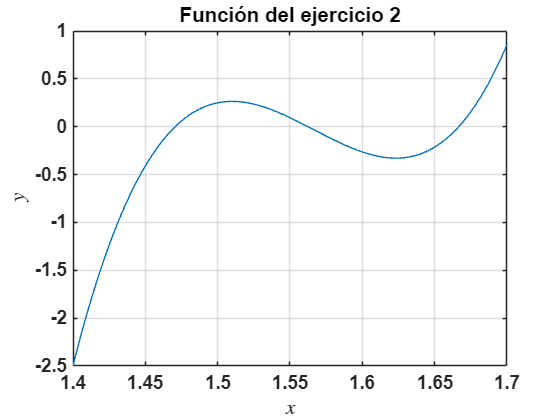

plot(linspace(1.4, 1.7), f(linspace(1.4, 1.7)))
grid on
title('Función del ejercicio 2')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
set(gca, 'FontName', 'Arial', 'FontSize', 14, 'FontWeight', 'Bold');

Después de algunas pruebas, se vió que la función `fzeros() `solo arroja un resultado cada vez que se usa, por lo cual, basándose en el gráfico, se reducirá el intervalo para que encuentre las 3 soluciones distintas.

fzero(f, [1.4 1.7])

ans = 1.6667

fzero(f, [1.5 1.6])

ans = 1.5625

fzero(f, [1.4 1.5])

ans = 1.4706

Se probaron distintos intervalos, en algunos casos, la función daba un error al poner puntos cuyas imágenes tenían el mismo signo, lo cual puede indicar que se utiliza el método de bisección en la función. Para comprobar esto, note que:

[x, fval, exitflag, output] = fzero(f, [1.4 1.7])

x = 1.6667

fval = 0

exitflag = 1

output = struct with fields:
    intervaliterations: 0
            iterations: 9
             funcCount: 11
             algorithm: 'bisection, interpolation'
               message: 'Zero found in the interval [1.4, 1.7]'


el parámetro *output* menciona que se usan los algoritmos de bisección e interpolación. Según lo explicado en clase, usualmente se combinan diversos métodos para hallar las raíces de una función, además, por el error que exige que las imágenes tengan distinto signo, se asume que inicialmente se utiliza el algoritmo de bisección y, posteriormente, el de interpolación.

**b)**

Para este caso iniciamos declarando algunas de las funciones que ocupamos. Se inició buscando un poco de la sintaxis de la creación de funciones en **MATLAB**, esto en la documentación oficial del programa (https://la.mathworks.com/help/matlab/ref/function.html).

Se encontraron algunos problemas al usar la función de Newton con vectores, por lo cual, estos se solucionaron aplicando la función `any `en la condición del while (https://la.mathworks.com/help/matlab/ref/any.html). Estos problemas se presentaban, probablemente, debido a que algunos valores iniciaban demasiado cerca del valor de convergencia, lo cual hace que la iteración se detenga rápidamente, pero esto entra en conflicto con los valores que no presentaban esa característica inicial, arrojando así valores erroneos.

% Derivada de f
fprima = @(x) (816 * 3 * (x .^ 2)) - (3835 * 2 * x) + 6000;

% Método para las iteraciones de Newton, basado en la función del método
% secante incluido en la plantilla de la tarea
function c = newton(fun, derivada, c0, epsilon)
    % Se calcula una iteración para iniciar la condición después
    c = c0 - (fun(c0) ./ derivada(c0));
    c1 = c0;

    % Se inicia la condición con los 2 valores correspondientes
    while any(abs(c - c1) > epsilon)
        c1 = c;
        c = c1 - (fun(c1) ./ derivada(c1));
    end
end

**c)**

Iniciamos con los valores iniciales que se requieren en el problema.

x0 = linspace(1.4,1.7);

Obtenemos los valores de convergencia con respecto a la función `f`.

valoresConv = newton(f, fprima, x0, (10 ^ -12));

Graficamos el resultado correspondiente.

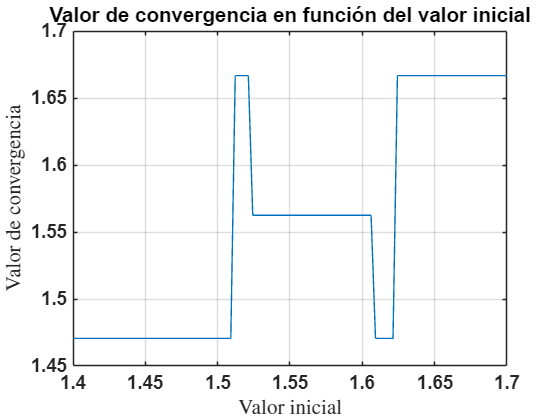

plot(x0, valoresConv)
grid on
title('Valor de convergencia en función del valor inicial')
xlabel('Valor inicial', 'Interpreter', 'latex')
ylabel('Valor de convergencia', 'Interpreter', 'latex')
set(gca, 'FontName', 'Arial', 'FontSize', 14, 'FontWeight', 'Bold');

**d)**

Para esta ocasión, ocupamos la segunda derivada de la funcion f, esta viene dada por:

fIIprima = @(x) 816 * 3 * 2 * x - 3835 * 2;

A continuación, se pretende graficar ambos lados de la desigualdad, esto para comparar visualmente si se cumple la cota para cada uno de los puntos.

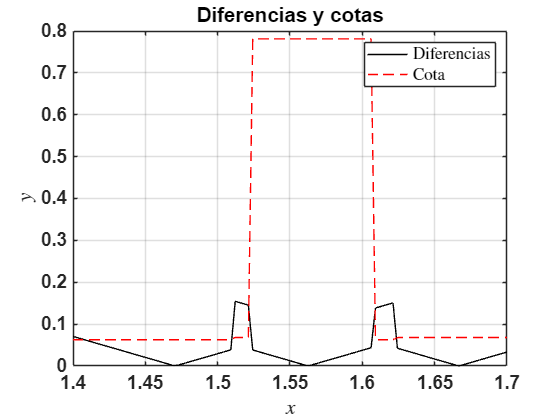

% Lado izquierdo de la desigualdad
valorC = abs(x0 - valoresConv);

% Lado derecho de la desigualdad
cota = (abs(fIIprima(valoresConv) ./ (2 * fprima(valoresConv)))) .^ -1;

% Grafico de comparación, basado en la plantilla de la tarea
figure;
plot(x0, valorC, 'k-', 'DisplayName', 'Diferencias');
hold on;

plot(x0, cota, 'r--', 'DisplayName', 'Cota');
grid on;

legend('show','Interpreter','Latex')

title('Diferencias y cotas');
xlabel('$x$','Interpreter','latex');
ylabel('$y$','Interpreter','latex');
set(gca,'FontName','Arial','FontSize',14,'FontWeight','Bold');

En este último gráfico se puede observar que la desigualdad no se cumple para todos los puntos, principalmente, en los intervalos antes y después de que la cota aumente, es decir, en esos intervalos se encuentran los estimados particularmente malos.

Note que los intervalos mencionados anteriormente coinciden en el comportamiento atípico del gráfico del valor de convergencia en función del valor inicial, pues, en este, uno esperaría un comportamiento de "escalera" hacia las raíces de la función, es decir, que al estar cerca de una de las soluciones, el algoritmo termine llegando a ella. Este comportamiento atípico puede deberse a que en esos intervalos no se cumple la desigualdad mencionada en el inciso:


$$|c_0 - c| \leq \left|\frac{f''(c)}{2 \cdot f'(c)} \right| ^ {-1}$$


lo cual queda claro en el último gráfico, por lo cual, esos intervalos no son parte de la base de atracción, eso hace que no haya garantía de que el algoritmo converja a un `c `que esté en el intervalo, dejando así, el comportamiento atípico en el gráfico de valores de convergencia según su valor inicial y la razón por la que estos son unos malos estimados.

**Pregunta 3. **La Ley de Enfriamiento de Newton dice que la razón de cambio de temperatura en el tiempo t de un objeto es proporcional a la diferencia entre la temperatura ambiente $T_a$ y la temperatura $T$ del objeto; i.e.,


$$\frac{dT}{dt} = k \cdot (T_a - T)$$


donde k es la constante de proporcionalidad.

**a)**

Iniciamos con la fórmula del inciso:


$$T(t) = T_a + (T_0 - T_a) \cdot e^{-kt}$$


Derivamos la misma:


$$\frac{\partial T}{\partial t} = (T_0 - T_a) \cdot e^{-kt} \cdot -k$$



$$\Longrightarrow \frac{\partial T}{\partial t} = -k \cdot (T_0 - T_a) \cdot e^{-kt}$$


Sumamos un cero:


$$\frac{\partial T}{\partial t} = -k \cdot (T_0 - T_a) \cdot e^{-kt} + k \cdot T_a - k \cdot T_a$$



$$\Longrightarrow \frac{\partial T}{\partial t} = k \cdot T_a - k \cdot (T_0 - T_a) \cdot e^{-kt} - k \cdot T_a$$



$$\Longrightarrow \frac{\partial T}{\partial t} = k \cdot T_a - k \left[(T_0 - T_a) \cdot e^{-kt} + T_a \right]$$


En este punto, note que $T = (T_0 - T_a) \cdot e^{-kt} + T_a$, por lo cual


$$\Longrightarrow \frac{\partial T}{\partial t} = k \cdot T_a - k \cdot T$$



$$\Longrightarrow \frac{\partial T}{\partial t} = k \cdot \left[T_a - T \right]$$


Lo cual es la fórmula de la ley de enfriamiento de Newton.

**b)**

Para encontrar el mínimo de este funcional, iniciamos expandiendo la fórmula con los valores adecuados.


$$\sum_i \left(T(t_i) - T_i \right) ^ 2$$



$$\Longrightarrow \left(T(t_0) - T_0\right) ^ 2 + \cdots +  \left(T(t_4) - T_4\right) ^ 2$$



$$\Longrightarrow \left(T_a + (T_0 - T_a) \cdot e ^ {-k \cdot t_0} - T_0\right) ^ 2 + \cdots + \left(T_a + (T_0 - T_a) \cdot e ^ {-k \cdot t_4} - T_4\right) ^ 2$$



$$\Longrightarrow (16 \cdot e^{-k \cdot 0.2} - 15.72) ^ 2 + (16 \cdot exp^{-k \cdot 0.4} - 15.41) ^ 2 + (16 \cdot exp^{-k \cdot 0.6} - 15.12) ^ 2 + (16 \cdot exp^{-k \cdot 0.8} - 14.9) ^ 2$$


Usando las constantes que da el problema, se pondrá lo anterior como una función que depende de la variable k.

funcional_enf = @(k) (16 * exp(-k * 0.2) - 15.72) .^ 2 + (16 * exp(-k * 0.4) - 15.41) .^ 2 + (16 * exp(-k * 0.6) - 15.12) .^ 2 + (16 * exp(-k * 0.8) - 14.9) .^ 2;

Ahora, graficaremos la función para hacernos una idea de cómo es:

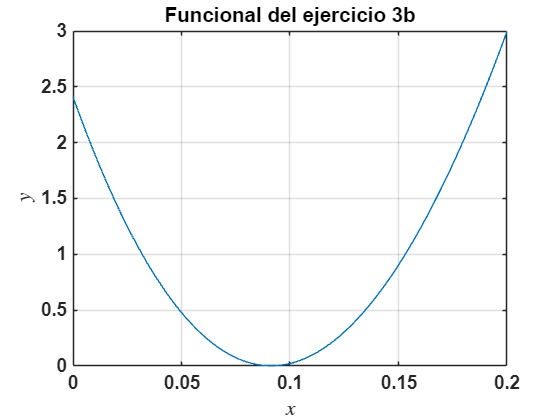

plot(linspace(0, 0.2), funcional_enf(linspace(0, 0.2)))
grid on
title('Funcional del ejercicio 3b')
xlabel('$x$', 'Interpreter', 'latex')
ylabel('$y$', 'Interpreter', 'latex')
set(gca, 'FontName', 'Arial', 'FontSize', 14, 'FontWeight', 'Bold');

Con esto, encontramos el mínimo con el método secante, esto ya que converge con mayor velocidad que el de bisección, sin embargo, el grupo considera que obtener la derivada de esta función para usar el método de Newton es innecesario, debido a que su derivada puede tener muchos términos, por lo cual, se considera el método secante otorgado por el profesor en la plantilla de la tarea.

function c1 = secante(f,c0,c1)
    for k = 1:10000
        cnew = c1-f(c1)*(c1-c0)/(f(c1)-f(c0));
        c0 = c1;
        c1 = cnew;
    end
end

El mínimo del funcional estaría dado por:

k = secante(funcional_enf, 0.05, 0.1)

k = 0.0915

Se comprueba que este es un mínimo, ya que:

funcional_enf(0.0915)

ans = 0.0018

El valor es aproximadamente 0.

**c)**

Ya que se pide el tiempo, iniciaremos despejando la ecuación correspondiente.


$$T = T_a + (T_0 - T_a) * e ^ {-k \cdot t}$$



$$\Longrightarrow T - T_a = (T_0 - T_a) * e ^ {-k \cdot t}$$



$$\Longrightarrow \frac{T - T_a}{T_0 - T_a} = e ^ {-k \cdot t}$$



$$\Longrightarrow ln \left(\frac{T - T_a}{T_0 - T_a} \right) = ln \left(e ^ {-k \cdot t} \right)$$



$$\Longrightarrow ln \left(\frac{T - T_a}{T_0 - T_a} \right) = -k \cdot t$$



$$\Longrightarrow \frac{ln \left(\frac{T - T_a}{T_0 - T_a} \right)}{-k} = t$$


Entonces, tomamos los valores del inciso:

$T_a = 31 \degree $, $T = 34\degree $, $T_0 = 37 \degree $

De forma que la persona falleció hace:

log(3 / 6) / -k

ans = 7.5761

horas.

**Pregunta 4. **A